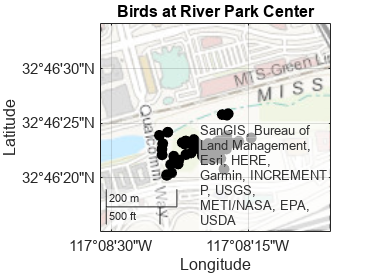

clf
data = readtable('observations-361592.csv'); % import data
coord = table2array(data(:,3:4)); % create coordinates array (lat, lon)
lat = coord(:,1);
lon = coord(:,2);

lat1 = 32.773; % latitude bound (southbound)
lat2 = 32.774; % latitude bound (northbound)
lon1 = -117.142; % longtitude (westbound)
lon2 = -117.135; % longitude (eastbound)

geolimits([lat1 lat2],[lon1 lon2]) % coordinate points River Park Center
geoplot(lat,lon,"ok",MarkerFaceColor="k") % plot all bird observations
title("Birds at River Park Center")
geobasemap topographic % display map type


spec = string(table2array(data(:,"scientific_name"))); % string array of species
crow = find(spec=='Corvus brachyrhynchos'); % index values of crows in data
coordc = [lat(crow),lon(crow)]; % coordincates crow observations

geolimits([lat1 lat2],[lon1 lon2]) % coordinate points River Park Center

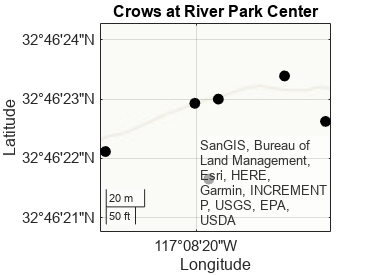

geoplot(lat(crow,:),lon(crow,:),"ok",MarkerFaceColor="k") % plot all crow observations 
title("Crows at River Park Center")
geobasemap topographic % display map type